%% データの読み込み
sub = 3; % 被験者の指定
filename = ['../../../materials/alpha_data_tsss/' 'sub' num2str(sub) '_alpha_data_tsss'];
dummy = ['load ' filename ' data_*'];
eval(dummy);

%% データの分割
cfg = [];
cfg.showcallinfo = 'no';
cfg.length = 10; % 2秒の時間窓
cfg.overlap = 0.5; % 時間窓のオーバーラップの割合 (この場合2秒*0.5=1秒)
data_o_crop = ft_redefinetrial(cfg, data_o);

the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials


data_c_crop = ft_redefinetrial(cfg, data_c);

the input is raw data with 204 channels and 6 trials
the input is raw data with 204 channels and 6 trials


%% FFT
cfg = [];
cfg.method = 'mtmfft';
cfg.showcallinfo = 'no';
cfg.taper = 'dpss';
cfg.tapsmofrq=1;
cfg.output = 'pow';
FFT_o = ft_freqanalysis(cfg, data_o_crop);

the input is raw data with 204 channels and 30 trials
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 30/30 nfft: 10000 samples, datalength: 10000 samples, 19 tapers



FFT_c = ft_freqanalysis(cfg, data_c_crop)

the input is raw data with 204 channels and 30 trials
Default cfg.pad='maxperlen' can run slowly. Consider using cfg.pad='nextpow2' for more efficient FFT computation.
processing trials
processing trial 30/30 nfft: 10000 samples, datalength: 10000 samples, 19 tapers



FFT_c = フィールドをもつ struct :
        label: {204×1 cell}
       dimord: 'chan_freq'
         freq: [0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1 1.1000 1.2000 1.3000 1.4000 1.5000 1.6000 1.7000 1.8000 1.9000 2 2.1000 2.2000 2.3000 2.4000 2.5000 2.6000 2.7000 2.8000 2.9000 3 3.1000 3.2000 3.3000 … ] (1×5001 double)
    powspctrm: [204×5001 double]
         grad: [1×1 struct]
          cfg: [1×1 struct]


cfg = [];
cfg.channel = {'MEGGRAD'};
cfg.combinemethod = 'sum';
cfg.showcallinfo = 'no';
FFT_o_cmb = ft_combineplanar(cfg, FFT_o);

the input is freq data with 204 channels, 5001 frequencybins and no timebins


FFT_c_cmb = ft_combineplanar(cfg, FFT_c);

the input is freq data with 204 channels, 5001 frequencybins and no timebins


[tmp, index] = sort(mean(FFT_o_cmb.powspctrm(:,8<FFT_o_cmb.freq&FFT_o_cmb.freq<13).'), 'descend');
Target_ch_o=index(1:10)

Target_ch_o =     74    62    16    90    13     7    79    72    50    59


[tmp, index] = sort(mean(FFT_c_cmb.powspctrm(:,8<FFT_c_cmb.freq&FFT_c_cmb.freq<13).'), 'descend');
Target_ch_c=index(1:10)

Target_ch_c =     79    78    74    72    77    62    90    71    64    75



%% 等磁界線図のためのパラメータ設定
cfg = [];
cfg.marker = 'on'; % センサの位置を表示
cfg.showcallinfo = 'no';
cfg.layout = 'neuromag306cmb'; % 今回のデータのMEGシステムを指定
cfg.xlim = [8 13]; % 8-13 Hzの平均パワーをプロット
cfg.colorbar = 'yes'; % スケールバーを表示
cfg.figure = 'gcf';
cfg.highlight = 'on'; % スペクトル計算に用いたセンサをハイライト
cfg.highlightcolor = [1 0 0]; % ハイライトの色を赤に設定
%% 上段左に開眼時，右に閉眼時の等磁界線図をプロット
figure;
subplot(2,2,1);
cfg.highlightchannel = Target_ch_o;
ft_topoplotTFR(cfg, FFT_o_cmb);

appending .lay to layout file
reading layout from file neuromag306cmb.lay


title('Open')
subplot(2,2,2);
cfg.highlightchannel = Target_ch_c;
ft_topoplotTFR(cfg, FFT_c_cmb);

appending .lay to layout file
reading layout from file neuromag306cmb.lay


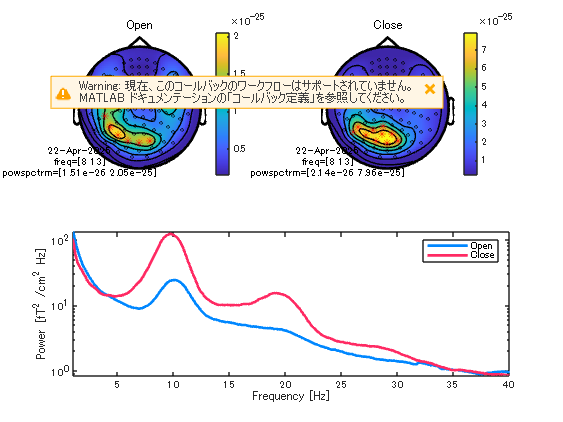

title('Close');
%% 選択されたセンサにわたって平均したパワースペクトルを描画
aveFFT_o = mean(FFT_o_cmb.powspctrm(Target_ch_o,:))*10^26; % [T 2 /m 2 Hz] -> [fT 2 /cm 2 Hz]
aveFFT_c = mean(FFT_c_cmb.powspctrm(Target_ch_c,:))*10^26; % [T 2 /m 2 Hz] -> [fT2 /cm 2 Hz]
subplot(2,1,2)
semilogy(FFT_o.freq, aveFFT_o,'Color',[0,135,255]/255,'LineWidth', 2);
hold on;
semilogy(FFT_c.freq, aveFFT_c,'Color',[255,42,99]/255,'LineWidth', 2);
xlim([1 40]);
legend('Open', 'Close')
xlabel('Frequency [Hz]');
ylabel('Power [fT^2 /cm^2 Hz]');


'Maximam power and index of open eyes'

ans = 'Maximam power and index of open eyes'

[power, freq] = max(aveFFT_o(8<FFT_o_cmb.freq&FFT_o_cmb.freq<13));
power

power = 24.1507

freq = FFT_o_cmb.freq(find((8<FFT_o_cmb.freq&FFT_o_cmb.freq<13),1)+freq)

freq = 10.2000

'Maximam power and index of closed eyes'

ans = 'Maximam power and index of closed eyes'

[power, freq] = max(aveFFT_c(8<FFT_c_cmb.freq&FFT_c_cmb.freq<13));
power

power = 121.6588

freq = FFT_c_cmb.freq(find((8<FFT_c_cmb.freq&FFT_c_cmb.freq<13),1)+freq)

freq = 9.9000